**Project 1: Numerical simulation of a model neuron**

Tasks:

1. Description of a neuron, numerical simulation of a model neuron: solving the system of differential equations using the Runge Kutta 4th order method, analyzing the correctness of choosing the time step.

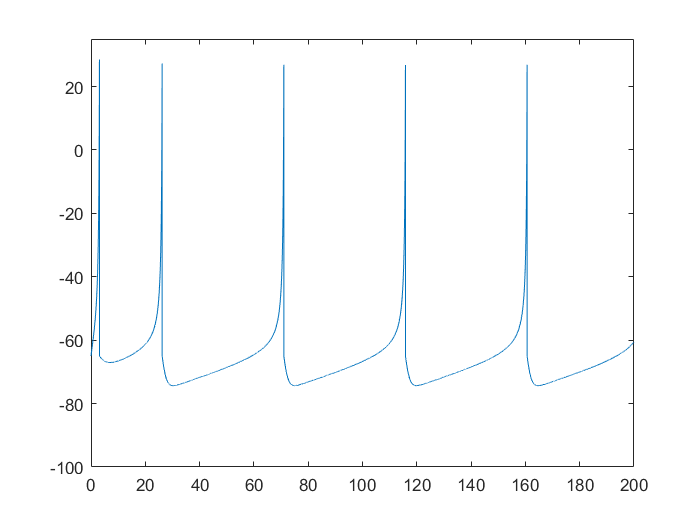

t=200;
dt=0.01;

a=0.02;
b=0.2;
c=-65;
d=8;
I=10;
v0=c;
u0=b*v0;
f0=[v0,u0];
const=[a,b,c,d,I];

fun=@Izhikevich_Neuron_model;
add_func=@After_spike_reset;

[f,dfdt]=RungeKutta(t,dt,f0,const,fun,add_func);
plot(f(:,1),f(:,2))
ylim([-100 35])

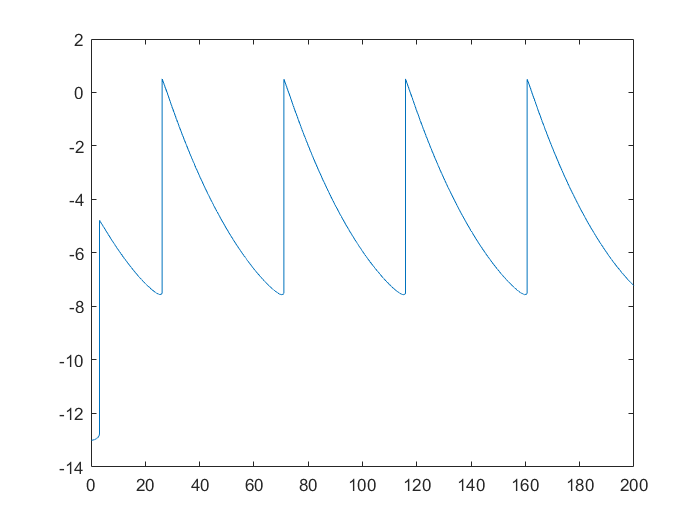

plot(f(:,1),f(:,3))

2. Analyzing different regimes of a neuron dynamics, plotting time series and phase portraits of the signal, calculation of a regime map.

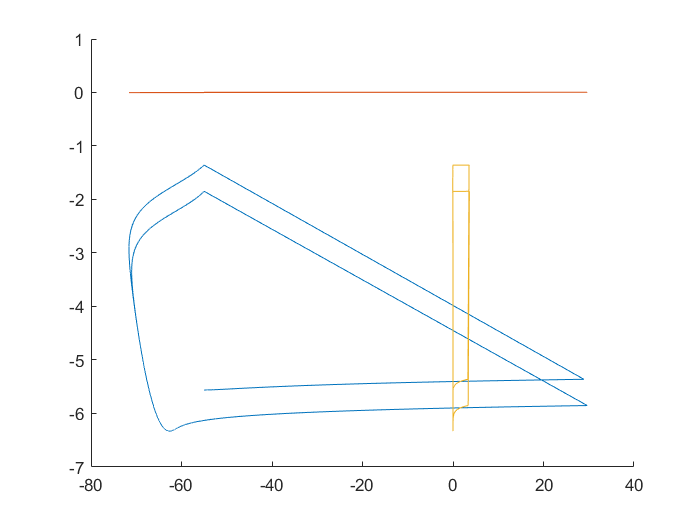

t=200;
dt=0.01;

a=0.05;
b=0.1011;
c=-55;
d=4;
I=10;
v0=c;
u0=b*v0;
f0=[v0,u0];
const=[a,b,c,d,I];

fun=@Izhikevich_Neuron_model;
add_func=@After_spike_reset;

[f,dfdt]=RungeKutta(t,dt,f0,const,fun,add_func);
figure()
hold on
plot(f(:,2),f(:,3))
plot(f(:,2),dfdt(:,3))
plot(dfdt(:,2),f(:,3))

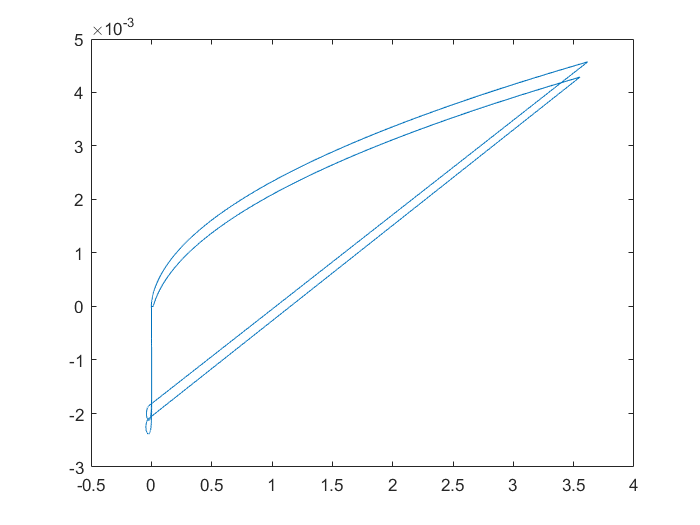

% xlim([-64 -59])
% ylim([-6.4 -6])
figure()
plot(dfdt(:,2),dfdt(:,3))

3. Adding Gaussian noise to the system, solving the system of differential equations with noise, analyzing the influence of noise amplitude on the system dynamics.

4. Adding the coupling between 2 neurons, analyzing synchronization between neurons for different values of the coupling strength.

5. Simulation of a neural network with global topology, analyzing the influence of external stimulus and noise amplitude by calculating characteristic correlation time.

function a=Inverse_kinematic_solver(A,B,C,mu_1)
if A==0 && B==0
    theta=inf;
elseif A==0
    theta=2*atan(-B/C);
elseif B^2<4*A*C
    theta=inf;
elseif B^2==4*A*C
    theta=2*atan(-B/(2*A));
elseif mu_1
    theta=2*atan((-B-sqrt(B^2-4*A*C))/(2*A));
else
    theta=2*atan((-B+sqrt(B^2-4*A*C))/(2*A));
end
end